# RX vs SSRX

Doron Serebro 07.05.2020

## Introduction

This notebook a working draft for the course project on the topic of "comparing RX and SSRX algorithms". The goal is to run RX and SSRX on the same dataset, find the differences and try to explain them in a meaningful way.

For now, this project is implemented on the RIT Blind Test data set.

## RX Algorithm

The RX algorithm is given by: $\textrm{RX}={\left(\overrightarrow{X} -\overrightarrow{m} \right)}^T \phi^{-1} \left(\overrightarrow{X} -\overrightarrow{m} \right)>\mathrm{Threshold}$. 

The threshold used in this implementation is  3-sigma: $\eta =\mu +3\sigma$, whre $\mu \;$is the mean RX score and $\sigma$ is the standard devation of the RX scores.

file = 'G:\My Drive\Project\self_test\HyMap\self_test_rad.img';
[mat,hdr] = auto_load_HS(file);

Loading ENVI header ...
Loading ENVI image ...


data=double(permute(mat,[2,1,3]));
[x_size,y_size, num_of_bands]=size(data);
[X_MINUS_M,phi]=HSI_MF_params(data);
phi_inv = pinv(phi);
RX = zeros(x_size,y_size);
for x = 1:x_size
    for y = 1:y_size
        x_minus_m = squeeze(X_MINUS_M(x,y,:));
        RX(x,y) = x_minus_m' * phi_inv * x_minus_m;
    end
end
RX= RX';
RX_filt = RX > mean(RX(:)) + 3*std(RX(:));

## SSRX Algorithm

The SSRX algorithm adds a preprocessing step to the RX algrotihm - performing PCA and keeping only low variance PCs.

the formula for PCA is given by: 


$$X_{\mathrm{PCA}} =\left(X-m\right)\phi {\;}^{-1} V_q$$



$$\begin{array}{l}
m-\textrm{the}\;\textrm{per}\;\textrm{channel}\;\textrm{mean}\;\textrm{of}\;X\\
\phi -\textrm{the}\;\textrm{covariance}\;\textrm{matrix}\\
V_q -a\;\textrm{matrix}\;\textrm{where}\;\textrm{every}\;\textrm{column}\;\textrm{is}\;\textrm{an}\;\textrm{eigen}\;\textrm{vector}\;\textrm{of}\;\phi \;\mathrm{while}\;\mathrm{ommiting}\;\mathrm{the}\;q\;\mathrm{eigen}\;\mathrm{vectors}\;\mathrm{that}\;\mathrm{correspond}\;\mathrm{to}\;\mathrm{the}\;\mathrm{highest}\;\mathrm{variance}\;\mathrm{eigen}\;\mathrm{values}
\end{array}$$


q = 120;
[V, D] = eigs(phi,126);
V2 = V(:,3:end);% deleting first 2 PC
V4 = V(:,5:end);% deleting first 4 PC
V6 = V(:,7:end);% deleting first 6 PC
data_pca2D2 = reshape(X_MINUS_M,x_size*y_size,num_of_bands) * V2;
data_pca2D4 = reshape(X_MINUS_M,x_size*y_size,num_of_bands) * V4;
data_pca2D6 = reshape(X_MINUS_M,x_size*y_size,num_of_bands) * V6;

data_pca2   = hyperConvert3d(data_pca2D2', x_size,y_size,num_of_bands);
data_pca4  = hyperConvert3d(data_pca2D4', x_size,y_size,num_of_bands);
data_pca6 = hyperConvert3d(data_pca2D6', x_size,y_size,num_of_bands);


Now that we have the preprocessed data, we can run the RX algorithm on it to get SSRX:

%calc phi_inv
[X_MINUS_M_PCA2,phi_pca2]=HSI_MF_params(data_pca2);
[X_MINUS_M_PCA4,phi_pca4]=HSI_MF_params(data_pca4);
[X_MINUS_M_PCA6,phi_pca6]=HSI_MF_params(data_pca6);

phi_pca_inv2 = pinv(phi_pca2);
phi_pca_inv4 = pinv(phi_pca4);
phi_pca_inv6 = pinv(phi_pca6);

%init empty results matrices
SSRX2   = zeros(x_size,y_size);
SSRX4  = zeros(x_size,y_size);
SSRX6 = zeros(x_size,y_size);

for x = 1:x_size
    for y = 1:y_size
        x_minus_m2 = squeeze(X_MINUS_M_PCA2(x,y,:));
        x_minus_m4 = squeeze(X_MINUS_M_PCA4(x,y,:));
        x_minus_m6 = squeeze(X_MINUS_M_PCA6(x,y,:));
        
        SSRX2(x,y) = x_minus_m2' * phi_pca_inv2 * x_minus_m2;
        SSRX4(x,y) = x_minus_m4' * phi_pca_inv4 * x_minus_m4;      
        SSRX6(x,y) = x_minus_m6' * phi_pca_inv6 * x_minus_m6;
    end
end
SSRX2= SSRX2';
SSRX4= SSRX4';
SSRX6= SSRX6';
SSRX2_filt = SSRX2 > mean(SSRX2(:)) + 3*std(SSRX2(:));
SSRX4_filt = SSRX4 > mean(SSRX4(:)) + 3*std(SSRX4(:));
SSRX6_filt = SSRX6 > mean(SSRX6(:)) + 3*std(SSRX6(:));

## Scatter Plot Comparison

Based on the results above, the difference between the 2 algorithms (if exists) is in the lower scored anomalies. Let's try to look at that:

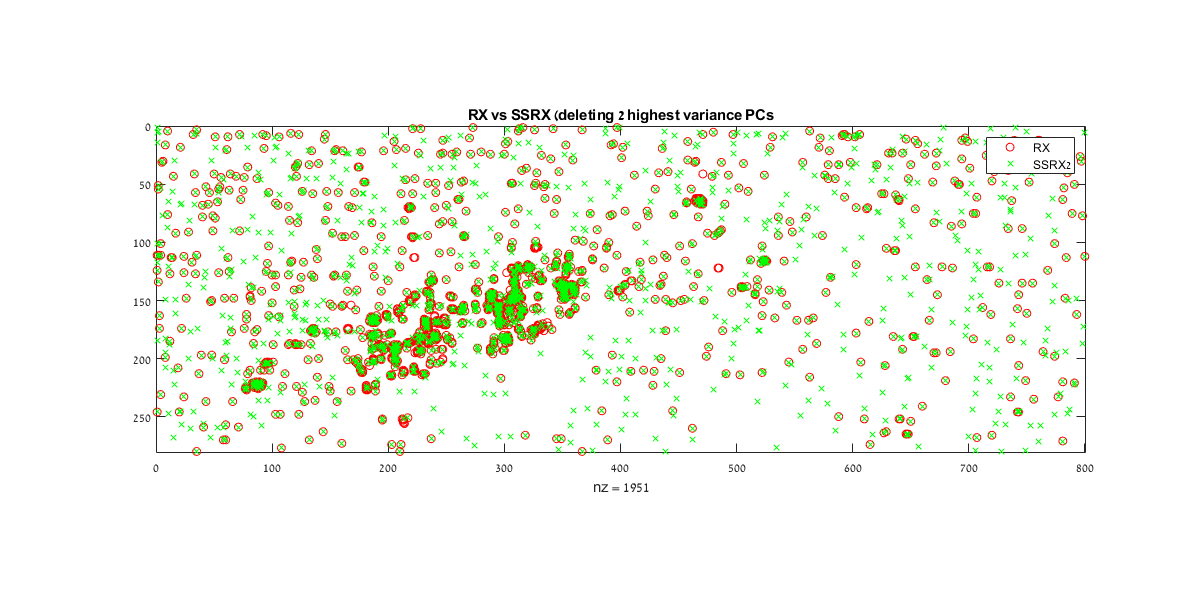

h1=figure; 
spy(RX_filt,'or'); 
hold on;
spy(SSRX2_filt,'xg');
legend('RX','SSRX2');
title('RX vs SSRX (deleting 2 highest variance PCs');
set(h1, 'Position', [0 0 1200 600])

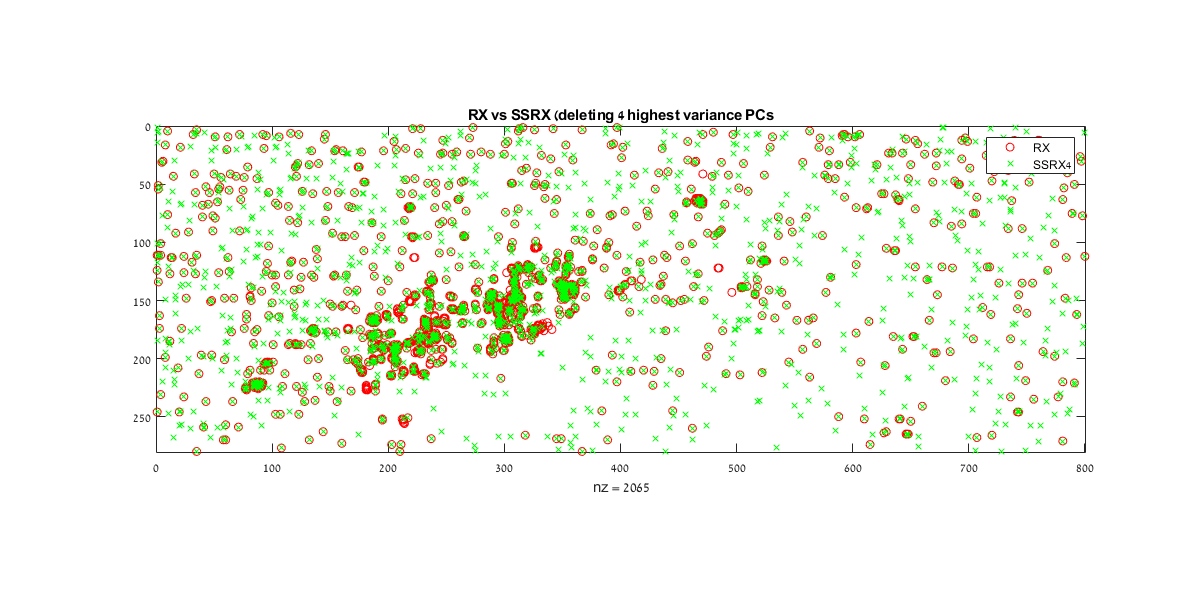

h2=figure; 
spy(RX_filt,'or'); 
hold on;
spy(SSRX4_filt,'xg');
legend('RX','SSRX4');
title('RX vs SSRX (deleting 4 highest variance PCs');
set(h2, 'Position', [0 0 1200 600])

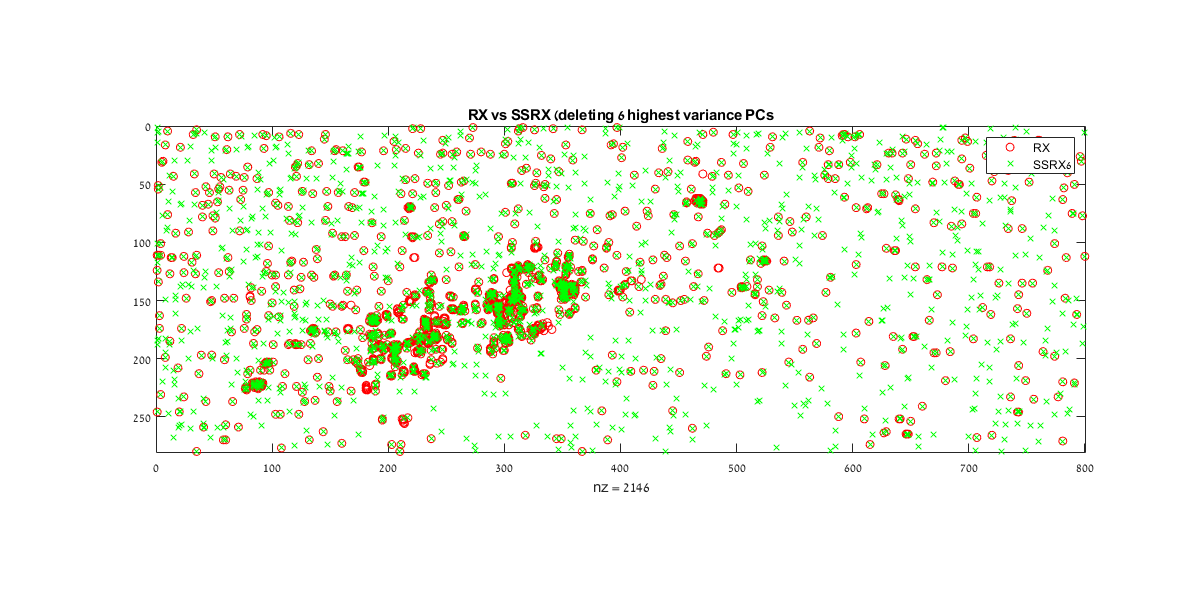

h3=figure; 
spy(RX_filt,'or'); 
hold on;
spy(SSRX6_filt,'xg');
legend('RX','SSRX6');
title('RX vs SSRX (deleting 6 highest variance PCs');
set(h3, 'Position', [0 0 1200 600])

**Conclusion:** The number of anomalies detected is increased with every PC removed.

## Anomalies Gained by SSRX

In order to characterize the difference in anomalies, let's examine what new anomalies were detected in the SSRX algorithm, but not in the RX algorithm.

number of anomalies SSRX2 detected that RX did not:

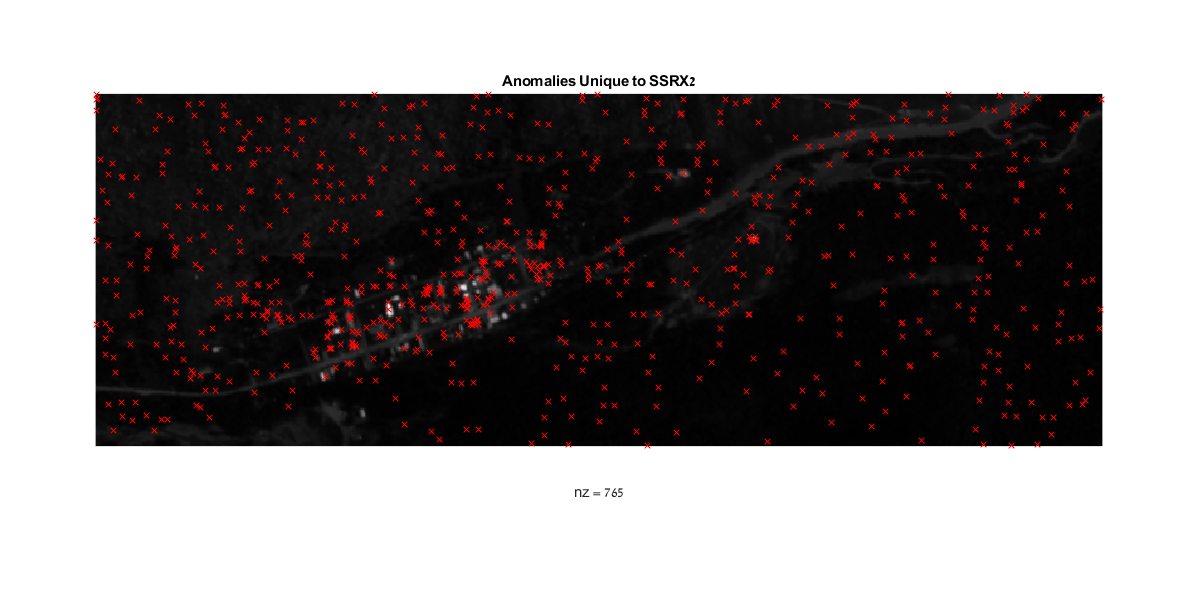

SSRX2_miss = SSRX2_filt.*(1-RX_filt);
% sum(nonzeros(SSRX2_diff))
h3=figure; 
imshow(data(:,:,1)',[]);
hold on;
spy(SSRX2_miss,'xr');
title('Anomalies Unique to SSRX2');
set(h3, 'Position', [0 0 1200 600])

number of anomalies SSRX4 detected that RX did not:

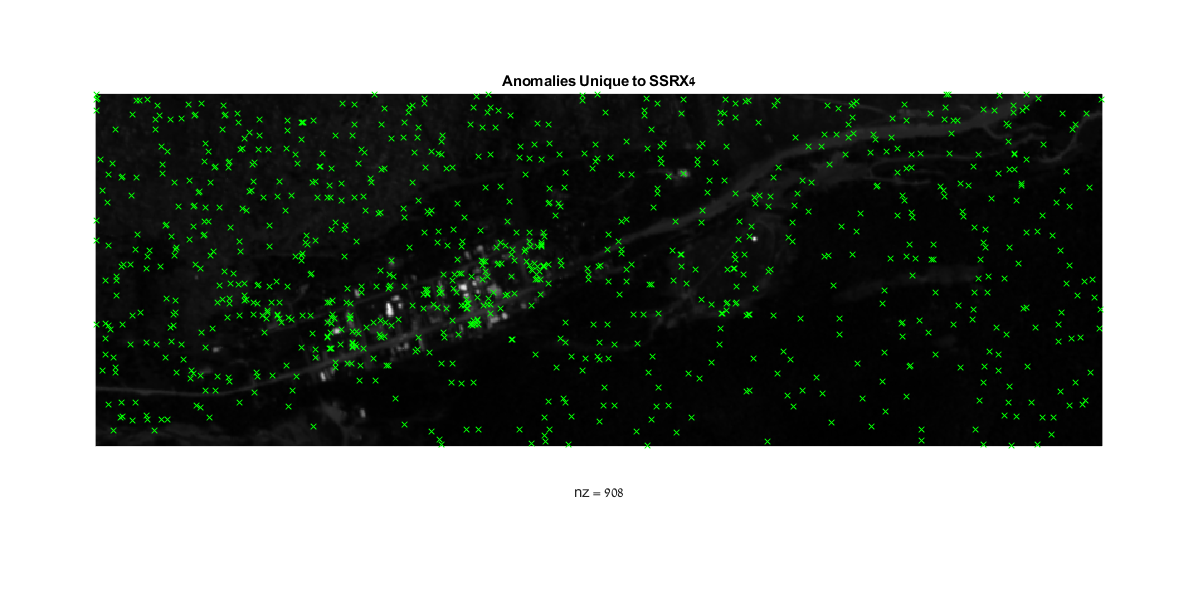

SSRX4_diff = SSRX4_filt.*(1-RX_filt);
% sum(nonzeros(SSRX4_diff))
h3=figure; 
 imshow(data(:,:,1)',[]);
hold on;
spy(SSRX4_diff,'xg');
title('Anomalies Unique to SSRX4');
set(h3, 'Position', [0 0 1200 600])

number of anomalies SSRX6 detected that RX did not:

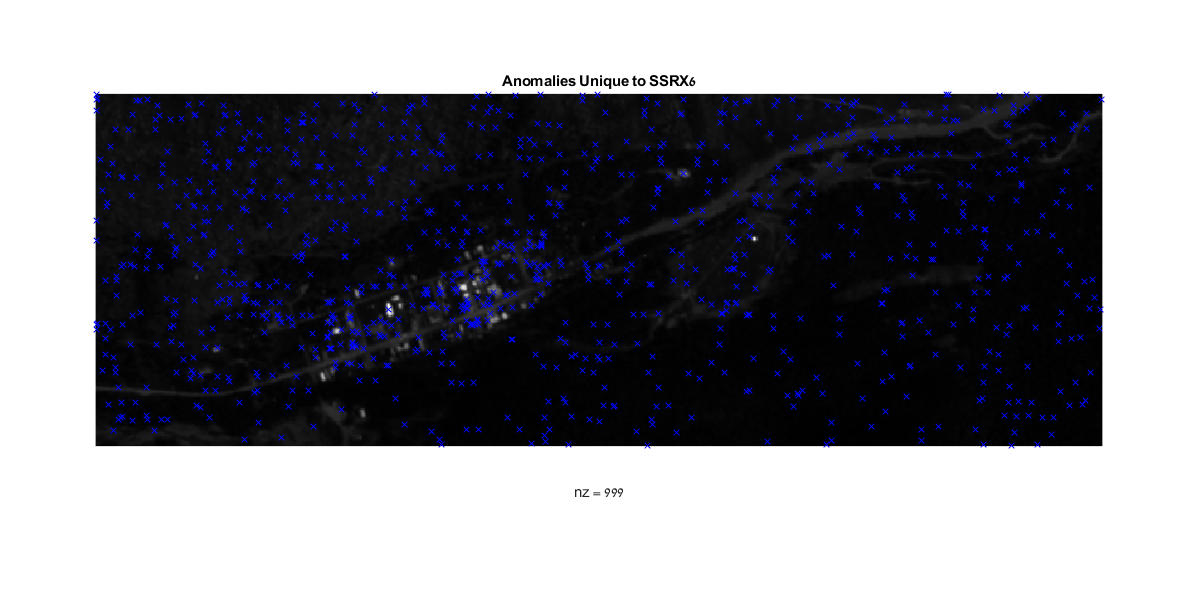

SSRX6_diff = SSRX6_filt.*(1-RX_filt);
% sum(nonzeros(SSRX6_diff))
h3=figure; 
 imshow(data(:,:,1)',[]);
hold on;
spy(SSRX6_diff,'xb');
title('Anomalies Unique to SSRX6');
set(h3, 'Position', [0 0 1200 600])

Conclusion: the more PCs we drop, the more noisy anomalies we get.

## Anomalies Missed by SSRX

Let's examine 

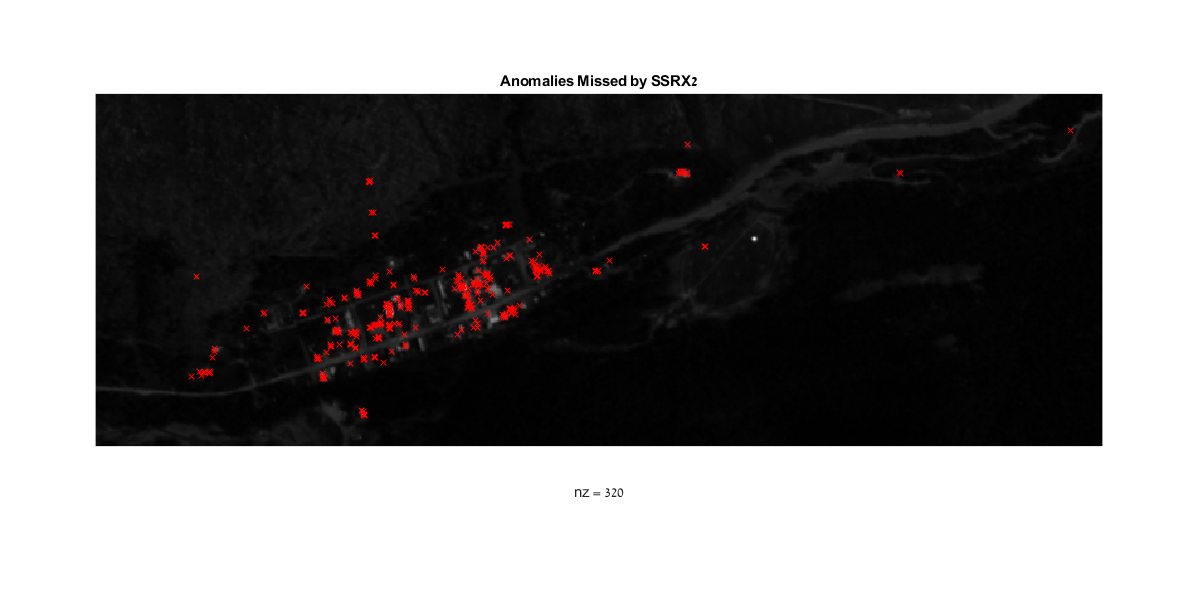

SSRX2_miss = (1-SSRX2_filt).*RX_filt;
% sum(nonzeros(SSRX2_diff))
h3=figure; 
imshow(data(:,:,1)',[]);
hold on;
spy(SSRX2_miss,'xr');
title('Anomalies Missed by SSRX2');
set(h3, 'Position', [0 0 1200 600])

number of anomalies SSRX4 detected that RX did not:

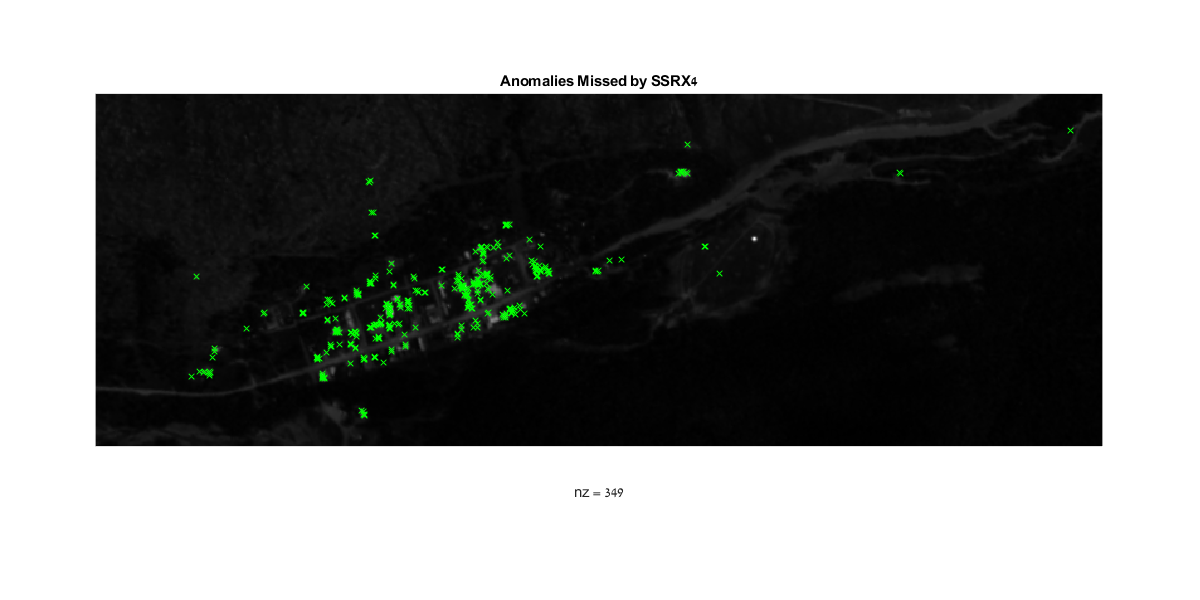

SSRX4_miss = (1-SSRX4_filt).*RX_filt;
% sum(nonzeros(SSRX4_diff))
h3=figure; 
 imshow(data(:,:,1)',[]);
hold on;
spy(SSRX4_miss,'xg');
title('Anomalies Missed by SSRX4');
set(h3, 'Position', [0 0 1200 600])

number of anomalies SSRX6 detected that RX did not:

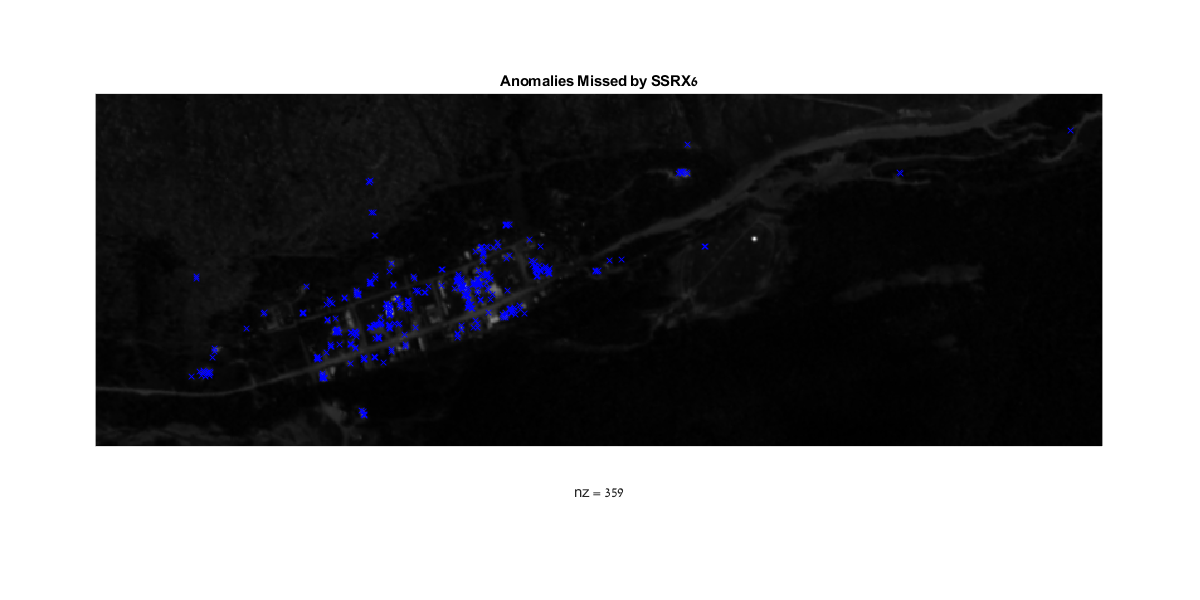

SSRX6_miss = (1-SSRX6_filt).*RX_filt;
% sum(nonzeros(SSRX6_diff))
h3=figure; 
 imshow(data(:,:,1)',[]);
hold on;
spy(SSRX6_miss,'xb');
title('Anomalies Missed by SSRX6');
set(h3, 'Position', [0 0 1200 600])

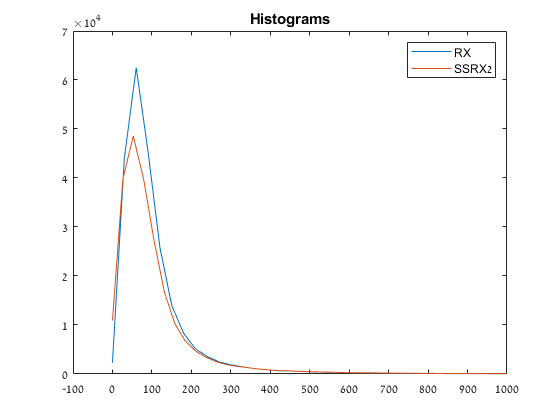

[RX_val,RX_bins]=histcounts(RX,1000);
[SSRX2_val,SSRX2_bins]=histcounts(SSRX2,1000);
% [SSRX4_val,SSRX4_bins]=histcounts(SSRX4,1000);
% [SSRX6_val,SSRX6_bins]=histcounts(SSRX6,1000);
figure;
plot(RX_bins(1:1000),RX_val);
hold on;
plot(SSRX2_bins(1:1000),SSRX2_val);
% plot(SSRX4_bins(1:1000),SSRX4_val);
% plot(SSRX6_bins(1:1000),SSRX6_val);
xlim([-100 1000]);
legend('RX','SSRX2');
title('Histograms');